## SIOT Data Analysis

This live script gets the syncronized emotion, heart pulse (PPG) and skin resistance data from ThingSpeak, then performs some time frequency analysis. The data was originally asyncronous, but has been processed by the "SyncronizeData.m" script which removes rows that are not common across all datasets.

#### Read data

Reads all ThingSpeak channel data then makes a table with just the syncronised data fields, as published by the "SyncronizeData.m" script. 

Note: Emotion numerical values set approximately by valence (very negative to very positive) and correspond as follows:

"2" = Happy

"1" = Surprised

"0" = Neutral

"-1" = Sad

"-2" = Scared 

"-3" = Disgusted

"-4" = Contemptuous

"-5" = Angry

clc
clear all

syncedChannelID = [1280543];
%syncedWriteKey = '';
%syncedReadKey = '';

%Ignore warning, set to 8000 which is server get limit
[Data,channelInfo] = thingSpeakRead(syncedChannelID,'OutputFormat','table','NumPoints',8000);

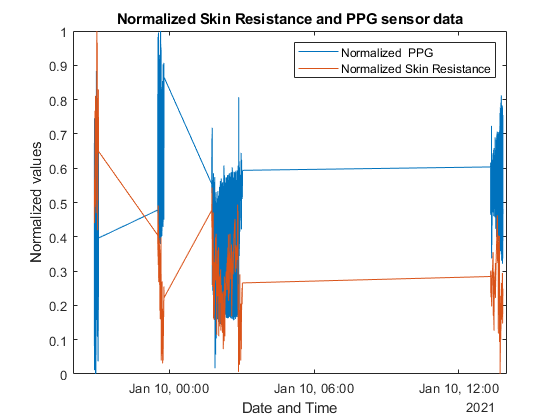


sTime = Data{:,1};
sPPG = Data{:,2};
sSkinResistance = Data{:,3};
sEmotions = timetable(sTime,Data{:,4});

%Get raw data mean and stabdard deviation; this will be needed to normalise
%the live incoming data.
rawPPG_std = std(sPPG);
rawSkinResistance_std = std(sSkinResistance);
rawPPG_mean = mean(sPPG);
rawSkinResistance_mean = mean(sSkinResistance);

%%PSEUDO-DATA FOR TESTING
%-----------------------------------------------------------------
% t1 = datetime(2021,1,10,8,0,1);
% t2 = datetime(2021,1,10,8,0,2);
% t3 = datetime(2021,1,10,8,0,3);
% t4 = datetime(2021,1,10,8,0,4);
% t5 = datetime(2021,1,10,8,0,5);
% t6 = datetime(2021,1,10,8,0,6);
% t7 = datetime(2021,1,10,8,0,7);
% t8 = datetime(2021,1,10,8,0,8);
% t9 = datetime(2021,1,10,8,0,9);
% t10 = datetime(2021,1,10,8,0,10);
% sTime = [t1 t2 t3 t4 t5 t6 t7 t8 t9 t10]';
% sPPG = [12 11 13 17 14 12 18 19 16 11]';
% sSkinResistance = [2 11 3 7 9 12 8 9 3 1]';
% sEmotions = [1 -2 0 3 1 0 -4 -4 -2 2]';
%%-----------------------------------------------------------------

%Normalized just non-categorical data since we need to get back emotions later, sPPG and sSkinResistance
sPPG = normalize(sPPG,'range');
sSkinResistance = normalize(sSkinResistance,'range');

%sanity check
plot(sTime,sPPG)
hold on
plot(sTime,sSkinResistance)
title("Normalized Skin Resistance and PPG sensor data")
xlabel("Date and Time")
ylabel("Normalized values")
legend("Normalized  PPG","Normalized Skin Resistance")
hold off


%Temporary sData timetable not including emotion data
sData = timetable(sTime, sPPG, sSkinResistance);

#### Find and remove outliers

Find PPG and Skin Resistance outliers (emotion outliers not found as it is a categorical tag), then remove corresponding emotions tags.

[sData2, TF] = rmoutliers(sData);
sData2 = outerjoin(sData2,sEmotions,'Keys', 'sTime', 'MergeKeys', 1);

%Final timetable and series
sData2 = rmmissing(sData2);
sTime = sData2.sTime;
sPPG = sData2{:,1};
sSkinResistance = sData2{:,2};
sEmotions = sData2{:,3};

#### Power spectrum and FFT - IGNORE

The sample rate for the recorded data was 1Hz for both the emotions and the sensor data. Calculating the power spectrum of the data after syncronisation will help to determine by how much the frequency has deviated from this ideal, serving as an evaluation for hardware performance. 

% % f = meanfreq(sPPG);
% % f = meanfreq(sSkinResistance);
% %
% % [sPPG_spectrum,f1] = pspectrum(sData(:,1));
% % [sSkinResistance_spectrum,f2] = pspectrum(sData(:,2));
% % [sEmotions_spectrum,f3] = pspectrum(sData(:,3));
% % % sPPG_spectrum = pxx(:,1);  %might be f here instead
% % % sSkinResistance_spectrum = pxx(:,2);
% % % sEmotions_spectrum = pxx(:,3);
% % 
% % plot(f1, sPPG_spectrum)
% % xlabel("Frequency (Hz)")
% % ylabel("Normalised signal values")
% % hold on
% % plot(f2, sSkinResistance_spectrum)
% % xlabel("Frequency (Hz)")
% % ylabel("Normalised signal values")
% % plot(f3, sEmotions_spectrum)
% % xlabel("Frequency (Hz)")
% % ylabel("Normalised signal values")
% % legend("PPG, pspectrum")
% % grid 
% % 
% % nfft = 256
% % nfft2 = 2^nextpow2(nfft);
% % fft1=fft(sPPG,nfft2)
% % plot(abs(fft1))
% % hold on 


#### Moving standard deviation

Calculate moving standard deviation over 1 minute windows.

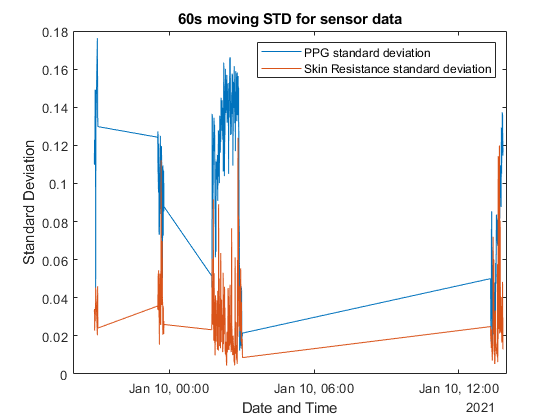

period = hours(1/60); %window
sPPG_movstd = movstd(sPPG,period,'SamplePoints',sTime);
sSkinResistance_movstd = movstd(sSkinResistance,period,'SamplePoints',sTime);
sEmotions_movstd = movstd(sEmotions,period,'SamplePoints',sTime);

plot(sTime, sPPG_movstd)
hold on
plot(sTime, sSkinResistance_movstd)
title("60s moving STD for sensor data")
xlabel("Date and Time")
ylabel("Standard Deviation")
legend("PPG standard deviation","Skin Resistance standard deviation")

hold off

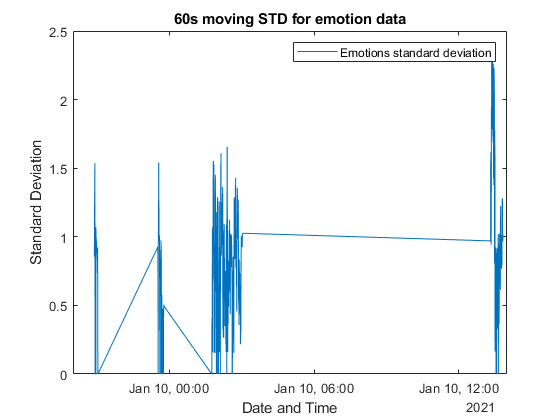


%Plot emotions std separately since it's not normalized from 0:1
plot(sTime, sEmotions_movstd)
title("60s moving STD for emotion data")
xlabel("Date and Time")
ylabel("Standard Deviation")
legend("Emotions standard deviation")

#### Windowed average and mode

Calculate and plot moving average over specified windows for sensor data and moving mode for emotion data (since it doesn't make sense to average categorical data). Note the slider to adjust window size; anything above 100 isn't recommended as the modal emotion turns out to always be "0" (Neutral) due to the 

e.g.: if window = 100, calculates mode and mean for indexes 1:101, then 101:201 and so on

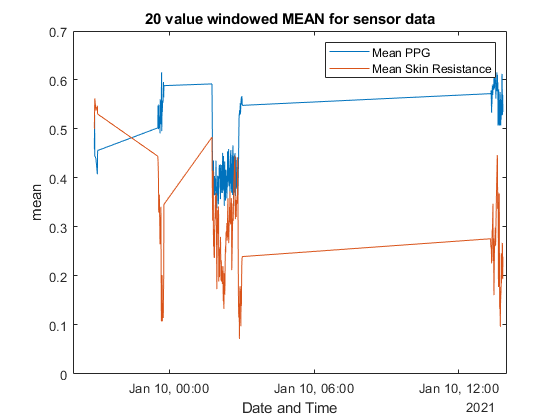

window = 20;
indexes = [1:window:size(sTime)];

%set custom functions for movingWindow
winmode = @(x) mode(x);
winmean = @(x) mean(x);

sPPG_winmean = matlab.tall.movingWindow(winmean,window,sPPG,"Stride",window);
sSkinResistance_winmean = matlab.tall.movingWindow(winmean,window,sSkinResistance,"Stride",window);
sEmotions_winmode = matlab.tall.movingWindow(winmode,window,sEmotions,"Stride",window);

%get corresponding times for plot
wintimes = [];
for i = indexes
    wintimes = [wintimes sTime(i,:)];
end

plot(wintimes,sPPG_winmean)
hold on
plot(wintimes,sSkinResistance_winmean)
title(window +" value windowed MEAN for sensor data")
xlabel("Date and Time")
ylabel("mean")
legend("Mean PPG", "Mean Skin Resistance")
hold off

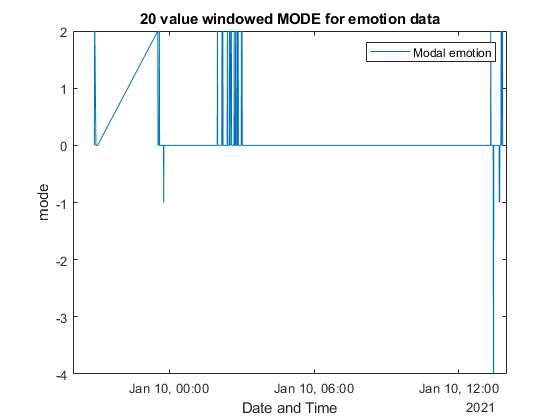


plot(wintimes,sEmotions_winmode)
title(window + " value windowed MODE for emotion data")
xlabel("Date and Time")
ylabel("mode")
legend("Modal emotion")

#### Distribution of emotions

Visualise distribution of emotions in bar chart.

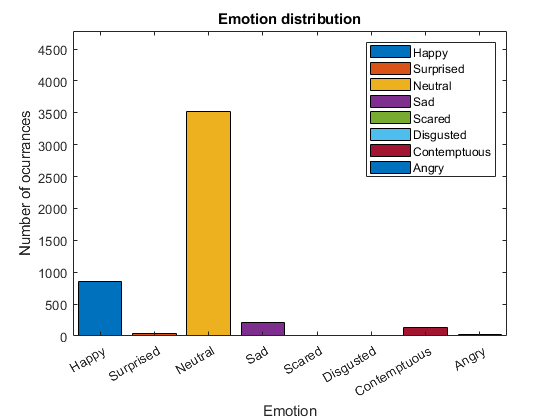

Happy = 0;
Surprised = 0;
Neutral = 0;
Sad = 0;
Scared = 0;
Disgusted = 0;
Contemptuous = 0;
Angry = 0;

for i = 1:length(sEmotions)
    if sEmotions(i)==2
        Happy=Happy+1;
    end
    if sEmotions(i)==1
        Surprised=Surprised+1;
    end
    if sEmotions(i)==0
        Neutral=Neutral+1;
    end
    if sEmotions(i)==-1
        Sad=Sad+1;
    end
    if sEmotions(i)==-2
        Scared=Scared+1;
    end
    if sEmotions(i)==-3
        Disgusted=Disgusted+1;
    end
    if sEmotions(i)==-4
        Contemptuous=Contemptuous+1;
    end
    if sEmotions(i)==-5
        Angry=Angry+1;
    end
end


Cats = categorical({'Happy', 'Surprised', 'Neutral', 'Sad', 'Scared', 'Disgusted', 'Contemptuous', 'Angry'});
Cats = reordercats(Cats,{'Happy', 'Surprised', 'Neutral', 'Sad', 'Scared', 'Disgusted', 'Contemptuous', 'Angry'});
emotionsCount = [Happy Surprised Neutral Sad Scared Disgusted Contemptuous Angry];
bar(Cats(:,1),emotionsCount(:,1))
hold on
bar(Cats(:,2),emotionsCount(:,2))
hold on
bar(Cats(:,3),emotionsCount(:,3))
hold on
bar(Cats(:,4),emotionsCount(:,4))
hold on
bar(Cats(:,5),emotionsCount(:,5))
hold on
bar(Cats(:,6),emotionsCount(:,6))
hold on
bar(Cats(:,7),emotionsCount(:,7))
hold on
bar(Cats(:,8),emotionsCount(:,8))
title("Emotion distribution")
xlabel("Emotion")
ylabel("Number of ocurrances")
legend('Happy','Surprised', 'Neutral', 'Sad', 'Scared', 'Disgusted', 'Contemptuous', 'Angry')
ylim([0,length(sEmotions)]);
hold off

#### Autocorrelation and cross-correlation

- Autocorrelation calculates how a series correlates with itself at different lags. This shows periodicity.

- Cross-correlation calculates how a series correlates with another series at different lags. 

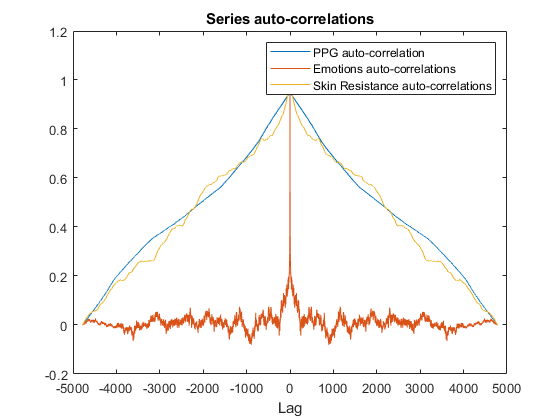

%Auto-correlations
[c1,lags1] = xcorr(sPPG,sPPG,"normalize");
plot(lags1,c1)
hold on
[c2,lags2] = xcorr(sEmotions,sEmotions,"normalize");
plot(lags2,c2)
hold on
[c3,lags3] = xcorr(sSkinResistance,sSkinResistance,"normalize");
plot(lags3,c3)
title("Series auto-correlations")
xlabel("Lag")
legend('PPG auto-correlation','Emotions auto-correlations', 'Skin Resistance auto-correlations')
hold off

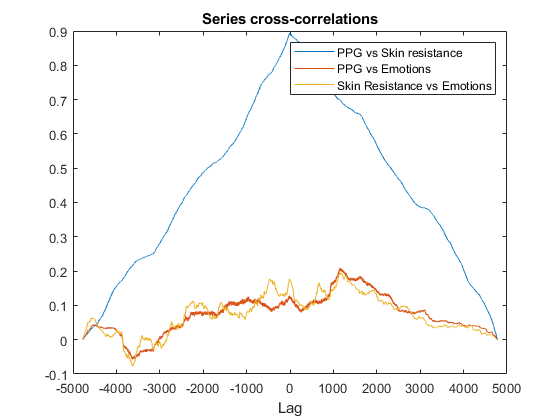


%Cross-correlations
[c1,lags1] = xcorr(sPPG,sSkinResistance,"normalize");
plot(lags1,c1)
hold on
[c2,lags2] = xcorr(sPPG,sEmotions,"normalize");
plot(lags2,c2)
hold on
[c3,lags3] = xcorr(sSkinResistance,sEmotions,"normalize");
plot(lags3,c3)
title("Series cross-correlations")
xlabel("Lag")
legend('PPG vs Skin resistance','PPG vs Emotions', 'Skin Resistance vs Emotions')
hold off